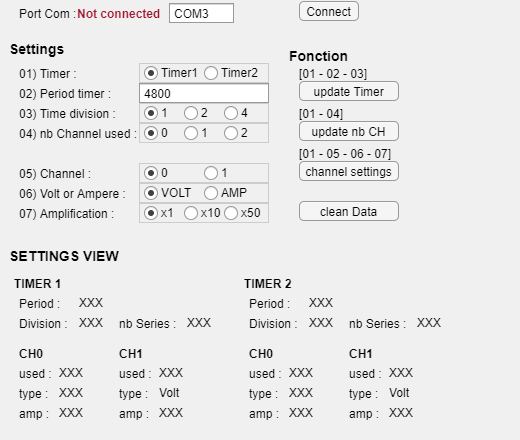

clc
% Create figure window and components
y = 440; x = 520;
x0 = 20;
x1 = 140;
x2 = 65;
pos = 20;
fig = uifigure('Position',[200 200 x y], ...
    'Name','SETTINGS DATA-Logger');
fig.Resize=0;

setappdata(fig, 's' ,0) ;

% connect
uilabel(fig, 'Position',[x0 y-pos 150 15], 'Text','Port Com :');
ulabConnec = uilabel(fig, 'Position',[x0+58 y-pos 150 15],'Text', 'Not connected',"FontWeight",'bold',"FontColor",'#A2142F');
comText = uitextarea(fig, 'Position',[x1+30 y-pos-2 x2 20],"Value",{'COM3'});

% param
lbl = uilabel(fig, 'Position', [10 y-pos*2.8 x1 17], 'Text','Settings',"FontWeight",'bold',"FontSize",14);

uilabel(fig, 'Position', [x0 y-pos*4 x1 15], 'Text','01) Timer :');
bgTIMER = uibuttongroup(fig,'Position',[x1 y-pos*4-2 130 20]);
rb1TIMER = uiradiobutton(bgTIMER,'Position',[5 0 60 20],"Text",'Timer1');
rb2TIMER = uiradiobutton(bgTIMER,'Position',[65 0 60 20],"Text",'Timer2');

uilabel(fig, 'Position', [x0 y-pos*5 x1 15], 'Text','02) Period timer :');
PresTimerText = uitextarea(fig, 'Position',[x1 y-pos*5-2 130 20],"Value",{'4800'});

uilabel(fig, 'Position', [x0 y-pos*6 x1 15], 'Text','03) Time division :');
bgCH = uibuttongroup(fig,'Position',[x1 y-pos*6-2 130 20]);
rb1div = uiradiobutton(bgCH,'Position',[5 0 60 20],"Text",'1');
rb2div = uiradiobutton(bgCH,'Position',[45 0 60 20],"Text",'2');
rb3div = uiradiobutton(bgCH,'Position',[85 0 60 20],"Text",'4');

uilabel(fig, 'Position', [x0 y-pos*7 x1 15], 'Text','04) nb Channel used :');
bgCH = uibuttongroup(fig,'Position',[x1 y-pos*7-2 130 20]);
rb1nbCH = uiradiobutton(bgCH,'Position',[5 0 60 20],"Text",'0');
rb2nbCH = uiradiobutton(bgCH,'Position',[45 0 60 20],"Text",'1');
rb3nbCH = uiradiobutton(bgCH,'Position',[85 0 60 20],"Text",'2');

uilabel(fig, 'Position', [x0 y-pos*9 x1 15], 'Text','05) Channel :');
bgCH = uibuttongroup(fig,'Position',[x1 y-pos*9-2 130 20]);
rb1CH = uiradiobutton(bgCH,'Position',[5 0 60 20],"Text",'0');
rb2CH = uiradiobutton(bgCH,'Position',[65 0 60 20],"Text",'1');

uilabel(fig, 'Position', [x0 y-pos*10 x1 15], 'Text','06) Volt or Ampere :');
bgVA = uibuttongroup(fig,'Position',[x1 y-pos*10-2 130 20]);
rb1VA = uiradiobutton(bgVA,'Position',[5 0 60 20],"Text",'VOLT');
rb2VA = uiradiobutton(bgVA,'Position',[65 0 60 20],"Text",'AMP');

uilabel(fig, 'Position', [x0 y-pos*11 x1 15], 'Text','07) Amplification :');
bgAMP = uibuttongroup(fig,'Position',[x1 y-pos*11-2 130 20]);
rb1AMP = uiradiobutton(bgAMP,'Position',[5 0 40 20],"Text",'x1');
rb2AMP = uiradiobutton(bgAMP,'Position',[45 0 40 20],"Text",'x10');
rb3AMP = uiradiobutton(bgAMP,'Position',[85 0 40 20],"Text",'x50');

%affichage
uilabel(fig, 'Position', [10 y-pos*13 x1 15], 'Text','SETTINGS VIEW',"FontWeight",'bold',"FontSize",14);

%TM1
uilabel(fig, 'Position', [15 y-pos*14.5 x1 15], 'Text','TIMER 1',"FontWeight",'bold');
uilabel(fig, 'Position', [x0 y-pos*15.5 x1 15], 'Text','Period :');
TM1P = uilabel(fig, 'Position', [80 y-pos*15.5-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0 y-pos*16.5 x1 15], 'Text','Division :');
TM1Div = uilabel(fig, 'Position', [80 y-pos*16.5-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0+100 y-pos*16.5 x1 15], 'Text','nb Series :');
TM1series = uilabel(fig, 'Position', [188 y-pos*16.5-2 130 20], 'Text','XXX');

uilabel(fig, 'Position', [x0 y-pos*18 x1 15], 'Text','CH0',"FontWeight",'bold');
uilabel(fig, 'Position', [x0 y-pos*19 x1 15], 'Text','used :');
TM1CH0use = uilabel(fig, 'Position', [60 y-pos*19-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0 y-pos*20 x1 15], 'Text','type :');
TM1CH0VA = uilabel(fig, 'Position', [60 y-pos*20-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0 y-pos*21 x1 15], 'Text','amp :');
TM1CH0Amp = uilabel(fig, 'Position', [60 y-pos*21-2 130 20], 'Text','XXX');

uilabel(fig, 'Position', [x0+100 y-pos*18 x1 15], 'Text','CH1',"FontWeight",'bold');
uilabel(fig, 'Position', [x0+100 y-pos*19 x1 15], 'Text','used :');
TM1CH1use = uilabel(fig, 'Position', [60+100 y-pos*19-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0+100 y-pos*20 x1 15], 'Text','type :');
uilabel(fig, 'Position', [60+100 y-pos*20-2 130 20], 'Text','Volt');
uilabel(fig, 'Position', [x0+100 y-pos*21 x1 15], 'Text','amp :');
TM1CH1Amp = uilabel(fig, 'Position', [60+100 y-pos*21-2 130 20], 'Text','XXX');

%TM2
uilabel(fig, 'Position', [15+230 y-pos*14.5 x1 15], 'Text','TIMER 2',"FontWeight",'bold');
uilabel(fig, 'Position', [x0+230 y-pos*15.5 x1 15], 'Text','Period :');
TM2P = uilabel(fig, 'Position', [80+230 y-pos*15.5-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0+230 y-pos*16.5 x1 15], 'Text','Division :');
TM2Div = uilabel(fig, 'Position', [80+230 y-pos*16.5-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0+100+230 y-pos*16.5 x1 15], 'Text','nb Series :');
TM2Series = uilabel(fig, 'Position', [188+230 y-pos*16.5-2 130 20], 'Text','XXX');

uilabel(fig, 'Position', [x0+230 y-pos*18 x1 15], 'Text','CH0',"FontWeight",'bold');
uilabel(fig, 'Position', [x0+230 y-pos*19 x1 15], 'Text','used :');
TM2CH0use = uilabel(fig, 'Position', [60+230 y-pos*19-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0+230 y-pos*20 x1 15], 'Text','type :');
TM2CH0VA = uilabel(fig, 'Position', [60+230 y-pos*20-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0+230 y-pos*21 x1 15], 'Text','amp :');
TM2CH0Amp = uilabel(fig, 'Position', [60+230 y-pos*21-2 130 20], 'Text','XXX');

uilabel(fig, 'Position', [x0+100+230 y-pos*18 x1 15], 'Text','CH1',"FontWeight",'bold');
uilabel(fig, 'Position', [x0+100+230 y-pos*19 x1 15], 'Text','used :');
TM2CH1use = uilabel(fig, 'Position', [60+100+230 y-pos*19-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0+100+230 y-pos*20 x1 15], 'Text','type :');
uilabel(fig, 'Position', [60+100+230 y-pos*20-2 130 20], 'Text','Volt');
uilabel(fig, 'Position', [x0+100+230 y-pos*21 x1 15], 'Text','amp :');
TM2CH1Amp = uilabel(fig, 'Position', [60+100+230 y-pos*21-2 130 20], 'Text','XXX');

%Button
uilabel(fig, 'Position', [290 y-pos*3 x1 15], 'Text','Fonction',"FontWeight",'bold',"FontSize",14);

uibutton(fig,'push', 'Position',[300, y-pos, 60, 20], 'Text', 'Connect', 'ButtonPushedFcn', ...
    @(btn,event) connect(fig,comText.Value,ulabConnec,TM1P,TM1Div,TM2P,TM2Div,TM1CH0use,TM1CH1use,TM2CH0use,TM2CH1use,TM1CH0VA,TM2CH0VA,TM1CH0Amp,TM1CH1Amp,TM2CH0Amp,TM2CH1Amp,TM1series,TM2Series));


uilabel(fig, 'Position', [300 y-pos*4 x1 15], 'Text','[01 - 02 - 03]');
uibutton(fig,'push', 'Position',[300, y-pos*5, 100, 20], 'Text', 'update Timer', 'ButtonPushedFcn', ...
    @(btn,event) sendPortComF01(fig,rb1TIMER.Value,PresTimerText.Value,rb1div.Value,rb2div.Value,TM1P,TM1Div,TM2P,TM2Div));

uilabel(fig, 'Position', [300 y-pos*6 x1 15], 'Text','[01 - 04]');
uibutton(fig,'push', 'Position',[300, y-pos*7, 100, 20], 'Text', 'update nb CH', 'ButtonPushedFcn', ...
    @(btn,event) sendPortComF02(fig,rb1TIMER.Value,rb1nbCH.Value,rb2nbCH.Value,TM1CH0use,TM1CH1use,TM2CH0use,TM2CH1use));

uilabel(fig, 'Position', [300 y-pos*8 x1 15], 'Text','[01 - 05 - 06 - 07]');
uibutton(fig,'push', 'Position',[300, y-pos*9, 100, 20], 'Text', 'channel settings', 'ButtonPushedFcn', ...
    @(btn,event) sendPortComF03(fig,rb1TIMER.Value,rb1CH.Value,rb1VA.Value,rb1AMP.Value,rb2AMP.Value,TM1CH0VA,TM2CH0VA,TM1CH0Amp,TM1CH1Amp,TM2CH0Amp,TM2CH1Amp));

clean = uibutton(fig,'push', 'Position',[300, y-pos*11, 100, 20], 'Text', 'clean Data');
yesDelet = uibutton(fig,'push', 'Position',[410, y-pos*11, 40, 20], 'Text', 'Yes',"Visible","off");
noDelet = uibutton(fig,'push', 'Position',[450, y-pos*11, 40, 20], 'Text', 'no',"Visible","off");

clean.ButtonPushedFcn= @(btn,event) cleanfonc(yesDelet,noDelet);
yesDelet.ButtonPushedFcn= @(btn,event) deleteData(fig,yesDelet,noDelet,TM1series,TM2Series);
    noDelet.ButtonPushedFcn= @(btn,event) resetClean(yesDelet,noDelet);

function connect (fig,com,text,TM1P,TM1Div,TM2P,TM2Div,TM1CH0use,TM1CH1use,TM2CH0use,TM2CH1use,TM1CH0VA,TM2CH0VA,TM1CH0Amp,TM1CH1Amp,TM2CH0Amp,TM2CH1Amp,TM1Series,TM2Series)
s = getappdata(fig, 's');
if(s == 0)
    clear('s');
    s = serialport(string(com),9600);
    setappdata(fig, 's' ,s)
    flush(s,"input");
    flush(s,"output");
    updateParam(fig,TM1P,TM1Div,TM2P,TM2Div,TM1CH0use,TM1CH1use,TM2CH0use,TM2CH1use,TM1CH0VA,TM2CH0VA,TM1CH0Amp,TM1CH1Amp,TM2CH0Amp,TM2CH1Amp,TM1Series,TM2Series);
    text.Text = 'Connected';
    text.FontColor='#77AC30';
end

end

function sendPortComF01(fig,rb1TIMER,PresTimerText,rb1div,rb2div,TM1P,TM1Div,TM2P,TM2Div)
s = getappdata(fig, 's');
tram = zeros(1,7,'uint8');
tram(1,1) = 0X01;
if(rb1TIMER)
    tram(1,2) = 0X0;
else
    tram(1,2) = 0X1;
end

X = uint32(0);
X(1,1) = str2double(PresTimerText);
y= typecast(X,'uint8');

tram(1,3)=y(1,1);
tram(1,4)=y(1,2);
tram(1,5)=y(1,3);
tram(1,6)=y(1,4);
if(rb1div)
    tram(1,7) = 0;
elseif (rb2div)
    tram(1,7) = 1;
else
    tram(1,7) = 2;
end

write(s,tram,"uint8");

RX_text = read(s,2,"uint8");

%update visu
if(RX_text(1)==0x10)
    if(rb1TIMER)
        TM1P.Text =  PresTimerText;
        if(rb1div)
            TM1Div.Text = "1";
        elseif (rb2div)
            TM1Div.Text = "2";
        else
            TM1Div.Text = "4";
        end
    else
        TM2P.Text =  PresTimerText;
        if(rb1div)
            TM2Div.Text = "1";
        elseif (rb2div)
            TM2Div.Text = "2";
        else
            TM2Div.Text = "4";
        end
    end
end
end

function sendPortComF02 (fig,rb1TIMER,rb1nbCH,rb2nbCH,TM1CH0use,TM1CH1use,TM2CH0use,TM2CH1use)
s = getappdata(fig, 's');
tram = zeros(1,3,'uint8');
tram(1,1) = 0X02;
if(rb1TIMER)
    tram(1,2) = 0;
else
    tram(1,2) = 1;
end
if(rb1nbCH)
    tram(1,3) = 0;
elseif(rb2nbCH)
    tram(1,3) = 1;
else
    tram(1,3) = 2;
end

write(s,tram,"uint8");
tram

RX_text = read(s,2,"uint8");
%update visu
if(RX_text(1)==0x10)
    if(rb1TIMER)
        if(rb1nbCH)
            TM1CH0use.Text = 'no';
            TM1CH1use.Text = 'no';
        elseif(rb2nbCH)
            TM1CH0use.Text = 'yes';
            TM1CH1use.Text = 'no';
        else
            TM1CH0use.Text = 'yes';
            TM1CH1use.Text = 'yes';
        end
    else
        if(rb1nbCH)
            TM2CH0use.Text = 'no';
            TM2CH1use.Text = 'no';
        elseif(rb2nbCH)
            TM2CH0use.Text = 'yes';
            TM2CH1use.Text = 'no';
        else
            TM2CH0use.Text = 'yes';
            TM2CH1use.Text = 'yes';
        end
    end
end
end

function sendPortComF03 (fig,rb1TIMER,rb1CH,rb1VA,rb1AMP,rb2AMP,TM1CH0VA,TM2CH0VA,TM1CH0Amp,TM1CH1Amp,TM2CH0Amp,TM2CH1Amp)
s = getappdata(fig, 's');
tram = zeros(1,5,'uint8');
tram(1,1) = 0X03;
if(rb1TIMER)
    tram(1,2) = 0;
else
    tram(1,2) = 1;
end
if(rb1CH)
    tram(1,3) = 0;
else
    tram(1,3) = 1;
end

if(rb1VA)
    tram(1,4) = 0;
else
    tram(1,4) = 1;
end

if(rb1AMP)
    tram(1,5) = 0;
elseif(rb2AMP)
    tram(1,5) = 1;
else
    tram(1,5) = 2;
end

write(s,tram,"uint8");
tram

RX_text = read(s,2,"uint8");

%update visu
if(RX_text(1)==0x10)
    if(rb1TIMER)
        if(rb1CH)
            if(rb1VA)
                TM1CH0VA.Text = 'Volt';
            else
                TM1CH0VA.Text = 'Ampere';
            end
            if(rb1AMP)
                TM1CH0Amp.Text = '*1';
            elseif(rb2AMP)
                TM1CH0Amp.Text = '*10';
            else
                TM1CH0Amp.Text = '*50';
            end
        else
            if(rb1AMP)
                TM1CH1Amp.Text = '*1';
            elseif(rb2AMP)
                TM1CH1Amp.Text = '*10';
            else
                TM1CH1Amp.Text = '*50';
            end
        end
    else
        if(rb1CH)
            if(rb1VA)
                TM2CH0VA.Text = 'Volt';
            else
                TM2CH0VA.Text = 'Ampere';
            end
            if(rb1AMP)
                TM2CH0Amp.Text = '*1';
            elseif(rb2AMP)
                TM2CH0Amp.Text = '*10';
            else
                TM2CH0Amp.Text = '*50';
            end
        else
            if(rb1AMP)
                TM2CH1Amp.Text = '*1';
            elseif(rb2AMP)
                TM2CH1Amp.Text = '*10';
            else
                TM2CH1Amp.Text = '*50';
            end
        end
    end

end
end


function updateParam(fig,TM1P,TM1Div,TM2P,TM2Div,TM1CH0use,TM1CH1use,TM2CH0use,TM2CH1use,TM1CH0VA,TM2CH0VA,TM1CH0Amp,TM1CH1Amp,TM2CH0Amp,TM2CH1Amp,TM1Series,TM2Series)
s = getappdata(fig, 's');
flush(s,"input");
tram = zeros(1,4,'uint8');

%period
tram(1,1) = 0X0B;
tram(1,2) = 0;
write(s,tram,"uint8");
readTX = read(s,7,"uint8");
TM1P.Text = string(readTX(1,3)*256*3+readTX(1,4)*256*2+readTX(1,5)*256*1+readTX(1,6));
TM1Div.Text = string(readTX(1,7));

tram(1,1) = 0X0B;
tram(1,2) = 1;
write(s,tram,"uint8");
readTX = read(s,7,"uint8");
TM2P.Text = string(readTX(3)*256*3+readTX(4)*256*2+readTX(5)*256*1+readTX(6));
TM2Div.Text = string(readTX(1,7));

tram(1,1) = 0X0A;
tram(1,2) = 0;
write(s,tram,"uint8");
readTX = read(s,4,"uint8");
TM1Series.Text = string(readTX(3)*256+readTX(4));

tram(1) = 0X0A;
tram(2) = 1;
write(s,tram,"uint8");
readTX = read(s,4,"uint8");
TM2Series.Text = string(readTX(3)*256+readTX(4));

%use
tram(1,1) = 0X0D;
tram(1,2) = 0;
write(s,tram,"uint8");
readTX = read(s,3,"uint8");
if(readTX(1,3)==0)
    TM1CH0use.Text = 'no';
    TM1CH1use.Text = 'no';
elseif(readTX(1,3)==1)
    TM1CH0use.Text = 'yes';
    TM1CH1use.Text = 'no';
elseif(readTX(1,3)==2)
    TM1CH0use.Text = 'yes';
    TM1CH1use.Text = 'yes';
else
    TM1CH0use.Text = 'XX';
    TM1CH1use.Text = 'XX';
end

tram(1,1) = 0X0D;
tram(1,2) = 1;
write(s,tram,"uint8");
readTX = read(s,3,"uint8");
if(readTX(1,3)==0)
    TM2CH0use.Text = 'no';
    TM2CH1use.Text = 'no';
elseif(readTX(1,3)==1)
    TM2CH0use.Text = 'yes';
    TM2CH1use.Text = 'no';
elseif(readTX(1,3)==2)
    TM2CH0use.Text = 'yes';
    TM2CH1use.Text = 'yes';
else
    TM2CH0use.Text = 'XX';
    TM2CH1use.Text = 'XX';
end

%TM1
tram(1,1) = 0X0C;
tram(1,2) = 0;
tram(1,3) = 0;
write(s,tram,"uint8");
readTX = read(s,5,"uint8");
if(readTX(1,4)== 0)
    TM1CH0VA.Text = 'Volt';
elseif(readTX(1,4)== 1)
    TM1CH0VA.Text = 'Ampere';
else
    TM1CH0VA.Text = 'XX';
end

if(readTX(1,5)==0)
    TM1CH0Amp.Text = '*1';
elseif(readTX(1,5)==1)
    TM1CH0Amp.Text = '*10';
elseif(readTX(1,5)==2)
    TM1CH0Amp.Text = '*50';
else
    TM1CH0Amp.Text = 'XX';
end

tram(1,1) = 0X0C;
tram(1,2) = 0;
tram(1,3) = 1;
write(s,tram,"uint8");
readTX = read(s,5,"uint8");

if(readTX(1,5)==0)
    TM1CH1Amp.Text = '*1';
elseif(readTX(1,5)==1)
    TM1CH1Amp.Text = '*10';
elseif(readTX(1,5)==2)
    TM1CH1Amp.Text = '*50';
else
    TM1CH1Amp.Text = 'XX';
end

%TM2
tram(1,1) = 0X0C;
tram(1,2) = 1;
tram(1,3) = 0;
write(s,tram,"uint8");
readTX = read(s,5,"uint8");

if(readTX(1,4)== 0)
    TM2CH0VA.Text = 'Volt';
elseif(readTX(1,4)== 1)
    TM2CH0VA.Text = 'Ampere';
else
    TM2CH0VA.Text = 'XX';
end
if(readTX(1,5)==0)
    TM2CH0Amp.Text = '*1';
elseif(readTX(1,5)==1)
    TM2CH0Amp.Text = '*10';
elseif(readTX(1,5)==2)
    TM2CH0Amp.Text = '*50';
else
    TM2CH0Amp.Text = 'XX';
end

tram(1,1) = 0X0C;
tram(1,2) = 1;
tram(1,3) = 1;
write(s,tram,"uint8");
readTX = read(s,5,"uint8");

if(readTX(1,5)==0)
    TM2CH1Amp.Text = '*1';
elseif(readTX(1,5)==1)
    TM2CH1Amp.Text = '*10';
elseif(readTX(1,5)==2)
    TM2CH1Amp.Text = '*50';
else
    TM2CH1Amp.Text = 'XX';
end
end

function cleanfonc(yesDelet,noDelet)
yesDelet.Visible = 'on';
noDelet.Visible = 'on';
end

function deleteData(fig,yesDelet,noDelet,TM1Series,TM2Series)
s = getappdata(fig, 's');
tram = zeros(1,1,'uint8');
tram(1) = 0x08;
write(s,tram,"uint8");
RX_text = read(s,2,"uint8")
if(RX_text(1)==0x10)
%dataDelet
TM1Series.Text='0';
TM2Series.Text='0';
resetClean(yesDelet,noDelet);
end
end

function resetClean(yesDelet,noDelet)
yesDelet.Visible = 'off';
noDelet.Visible = 'off';
end